- **Change the window sizes – has the frequency resolution changed?**

Yes, the frequency resolution changes with the change in window size. A larger window size gives higher spectral and lower temporal resolution, and vice versa.

- **How can you find out frequency resolution from the outputs?**

The frequency resolution can be found from the output by giving the following command:

[y,f,t,p] = spectrogram(signal);

here, p is the frequency vector, nd the resolution can be found from here.

- **Can you justify the change in frequency resolution?**

The window is convoluted with the original signal in the frequency domain causing a change in the resolution.

- **Keeping window sizes fixed, can you double the frequency resolution? How?**

Yes, we can add zero padding to increase the frequency resolution. However, this will not increase the signal information content.

## Sine

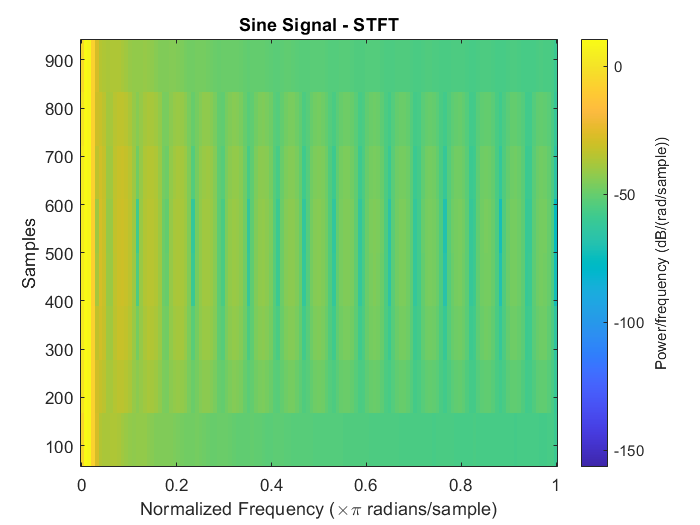

close all
t = 0 : 1/1000 : 1;
f1 = 5; 
T1 = 1/f1;
amp1 = 1; 
signal = amp1 * sin(2*pi*t/T1);
%subplot(3,2,1)
spectrogram(signal); %STFT
title ('Sine Signal - STFT')

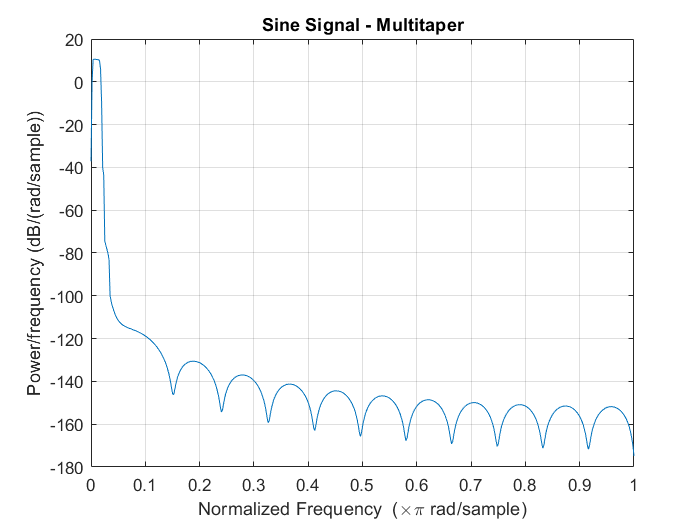

%subplot(3,2,3)
pmtm(signal); %MultiTaper
title ('Sine Signal - Multitaper')

%pbaspect([1 1 1])
%subplot(3,1,3)

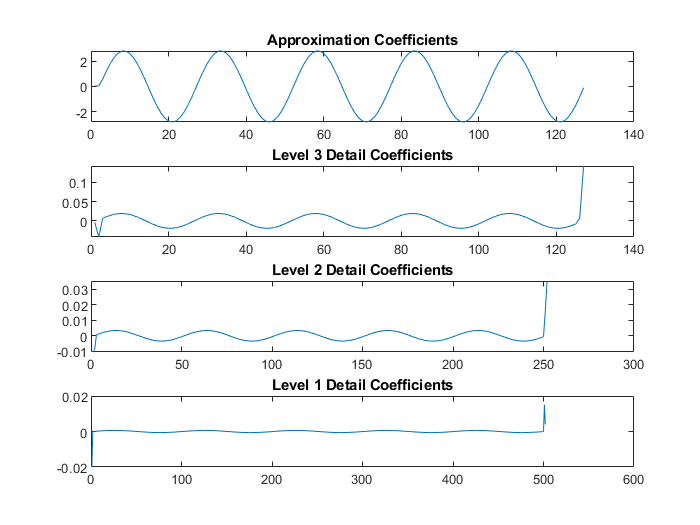

close all
clear all
t = 0 : 1/1000 : 1;
f1 = 5; 
T1 = 1/f1;
amp1 = 1; 
signal = amp1 * sin(2*pi*t/T1);

[c,l] = wavedec(signal,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

## Log Chirp

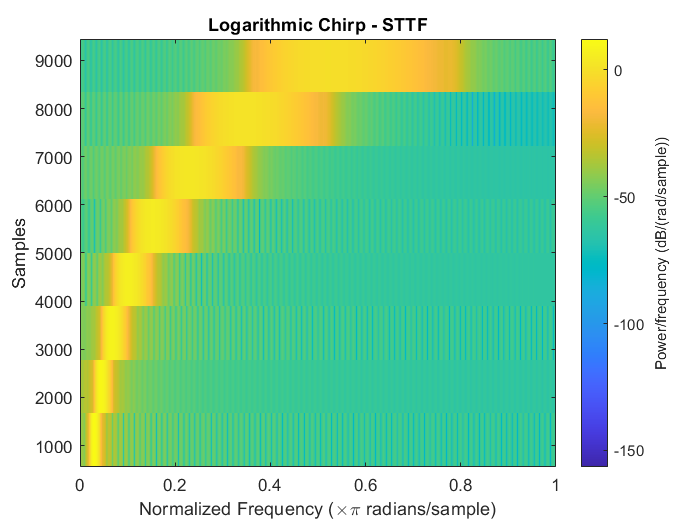

close all
clear all
t= 0:0.001:10; 
signal=chirp(t,10,10,400,'logarithmic');
%subplot(3,1,1)
spectrogram(signal);
title ('Logarithmic Chirp - STTF')

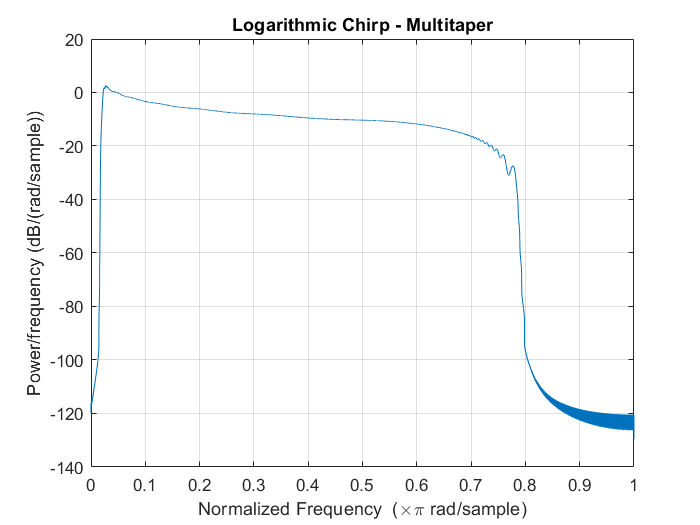

%subplot(3,1,2)
pmtm(signal);
title ('Logarithmic Chirp - Multitaper')

%subplot(3,1,3)

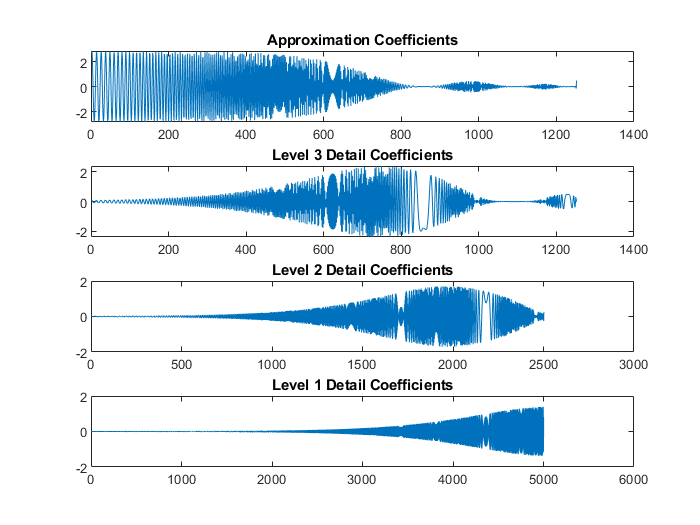

close all
clear all
t= 0:0.001:10; 
signal=chirp(t,10,10,400,'logarithmic');

[c,l] = wavedec(signal,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

## Quadratic Chirp

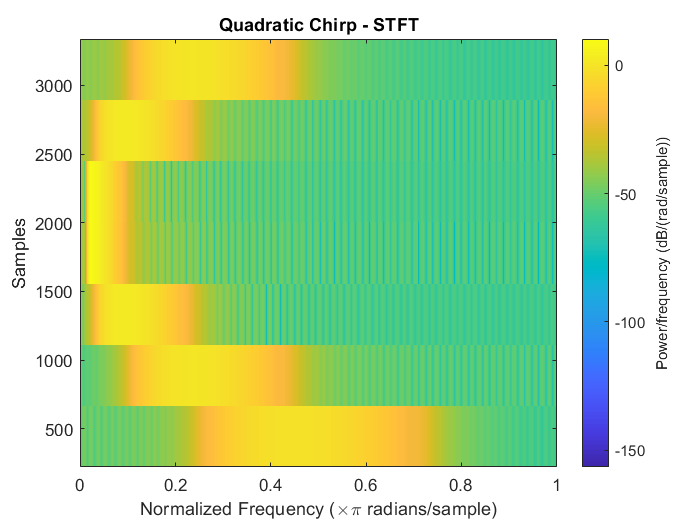

clear all
close all
t=-2:0.001:2;                  
signal=chirp(t,10,1,100,'q');   
%subplot(3,1,1)
spectrogram(signal);
title ('Quadratic Chirp - STFT')

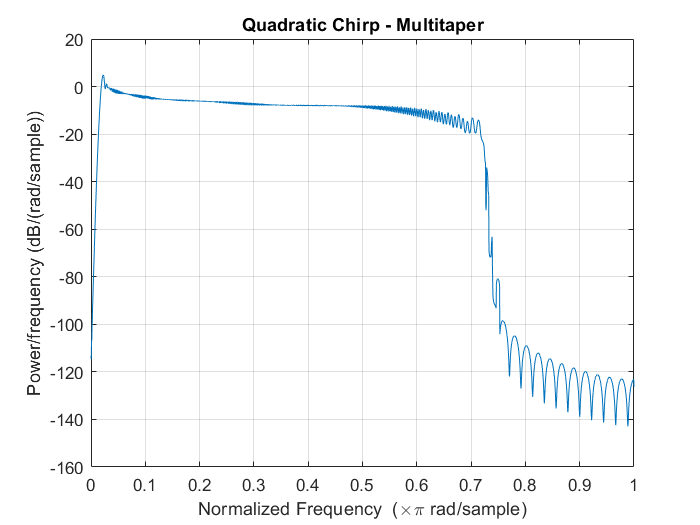

%subplot(3,1,2)
pmtm(signal);
title ('Quadratic Chirp - Multitaper')

%subplot(3,1,3)

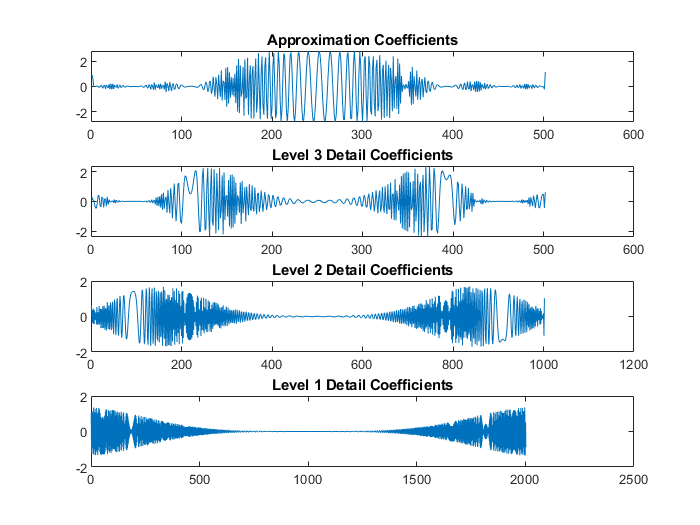

clear all
close all
t=-2:0.001:2;                  
signal=chirp(t,10,1,100,'q');  
[c,l] = wavedec(signal,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

## Linear Chirp

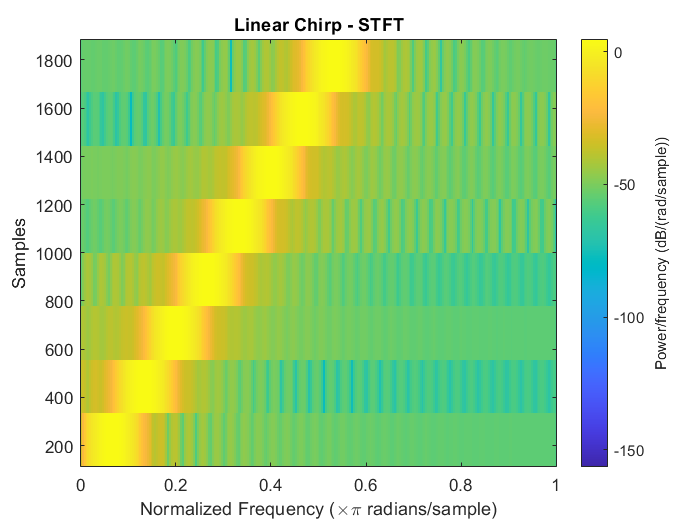

clear all
close all
t=0:0.001:2; 
signal=chirp(t,0,1,150);  
%subplot(3,1,1)
spectrogram(signal);
title ('Linear Chirp - STFT')

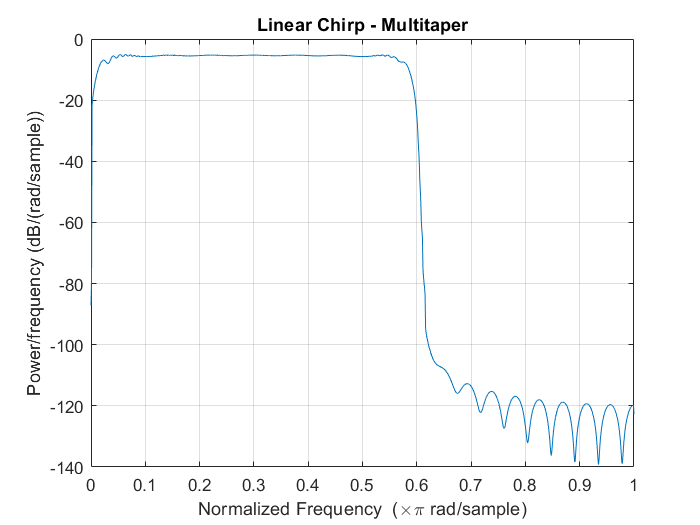

%subplot(3,1,2)
pmtm(signal);
title ('Linear Chirp - Multitaper')

%subplot(3,1,3)

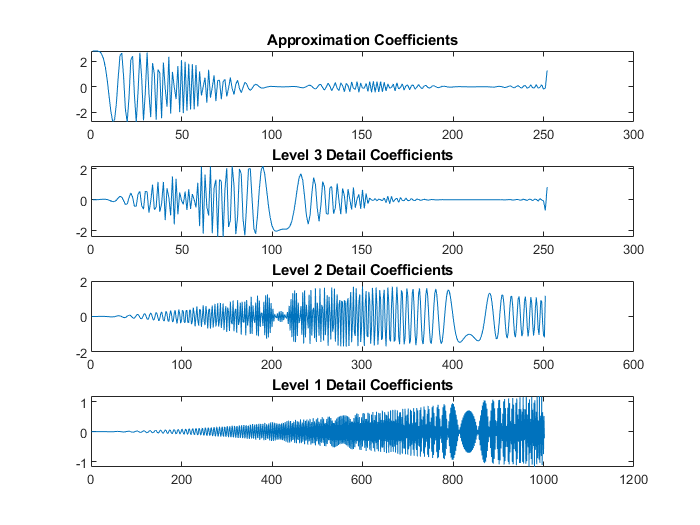

clear all
close all
t=0:0.001:2; 
signal=chirp(t,0,1,150);  
[c,l] = wavedec(signal,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')

## Concave Chirp

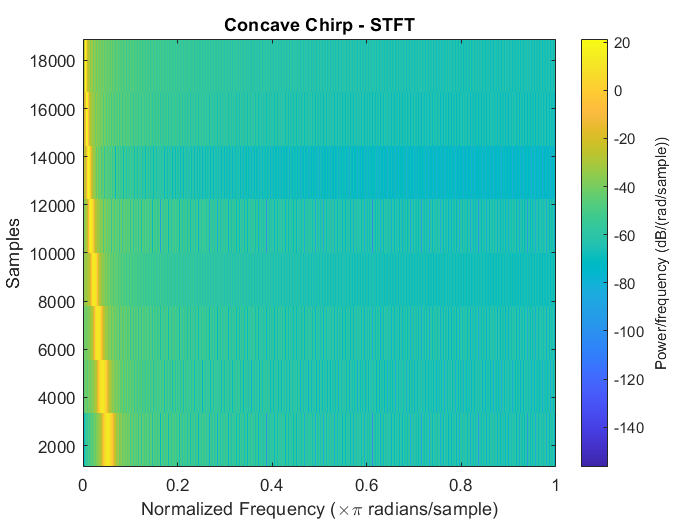

clear all
close all
t= 0:0.0001:2;
signal=chirp(t,100,1,25,'q',[],'concave');
%subplot(3,1,1)
spectrogram(signal);
title ('Concave Chirp - STFT')

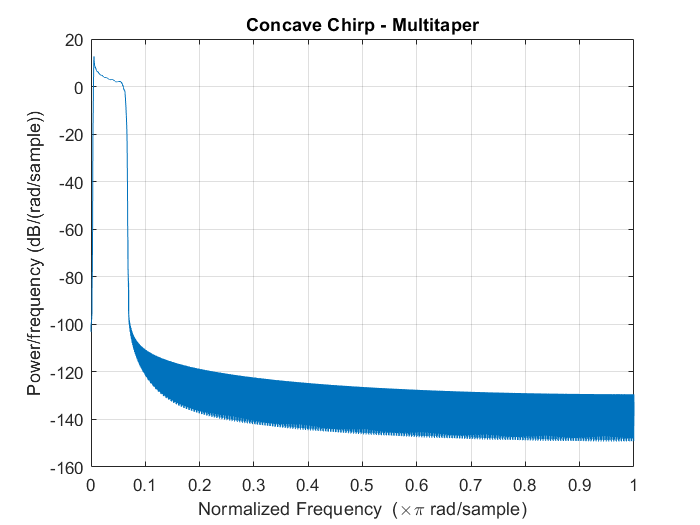

%subplot(3,1,2)
pmtm(signal);
title ('Concave Chirp - Multitaper')

%subplot(3,1,3)


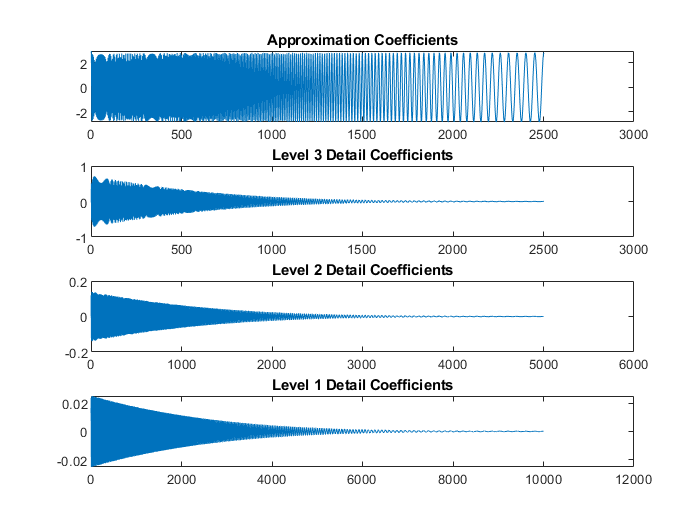

clear all
close all
t= 0:0.0001:2;
signal=chirp(t,100,1,25,'q',[],'concave');
[c,l] = wavedec(signal,3,'db2');
approx = appcoef(c,l,'db2');
[cd1,cd2,cd3] = detcoef(c,l,[1 2 3]);

subplot(4,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(4,1,2)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(4,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(4,1,4)
plot(cd1)
title('Level 1 Detail Coefficients')